clear all
d1=load("E:\MTP2\precipitation\processed\PPT_monthly_mean.mat");
d2=load("E:\MTP2\Soil moisture\processed\SM_monthly_mean.mat");
d3=load("E:\MTP2\L band VOD\processed\VOD_monthly_mean.mat");
d4=load("E:\MTP2\SIF data\processed\SIF_monthly_mean.mat");
d5=load("E:\MTP2\VODCA VOD\VOD_X_monthly_mean_unmasked.mat");
d6=load("E:\MTP2\VODCA VOD\VOD_C_monthly_mean_unmasked.mat");

ppt=d1.B;
sm=d2.SM;
vod=d3.VOD;
vod_x=d5.VOD;
vod_c=d6.VOD;
sif=d4.SIF;

m1=load("E:\MTP2\precipitation\PPT_longterm_mean.mat");
s1=load("E:\MTP2\precipitation\PPT_longterm_std.mat");
m2=load("E:\MTP2\Soil moisture\masking\SM_longterm_mean.mat");
s2=load("E:\MTP2\Soil moisture\masking\SM_longterm_std.mat");
m3=load("E:\MTP2\L band VOD\masking\VOD_longterm_mean.mat");
s3=load("E:\MTP2\L band VOD\masking\VOD_longterm_std.mat");
m4=load("E:\MTP2\SIF data\SIF_longterm_mean.mat");
s4=load("E:\MTP2\SIF data\SIF_longterm_std.mat");
m5=load("E:\MTP2\VODCA VOD\masking X\VOD_X_longterm_mean.mat");
s5=load("E:\MTP2\VODCA VOD\masking X\VOD_X_longterm_std.mat");
m6=load("E:\MTP2\VODCA VOD\masking C\VOD_C_longterm_mean.mat");
s6=load("E:\MTP2\VODCA VOD\masking C\VOD_C_longterm_std.mat");

ppt_m=m1.AVG;
sm_m=m2.AVG;
vod_m=m3.AVG;
vod_x_m=m5.AVG;
vod_c_m=m6.AVG;
sif_m=m4.AVG;
ppt_s=s1.STD;
sm_s=s2.STD;
vod_s=s3.STD;
vod_x_s=s5.STD;
vod_c_s=s6.STD;
sif_s=s4.STD;

year=2018;

x1=80;
y1=59;
lat=ppt(x1,1,1);
long=ppt(1,y1,1);

for p=1:132
    if (floor(ppt(1,1,p)/100))==year
        ind_start=p;
        break
    end
end
ind_end=ind_start+11;

mo=1:12;

for k=1:12
    m(k)=month(datetime(1,k,1), 'name');
end

mon=["Feb","Apr","Jun","Aug","Oct","Dec"]';


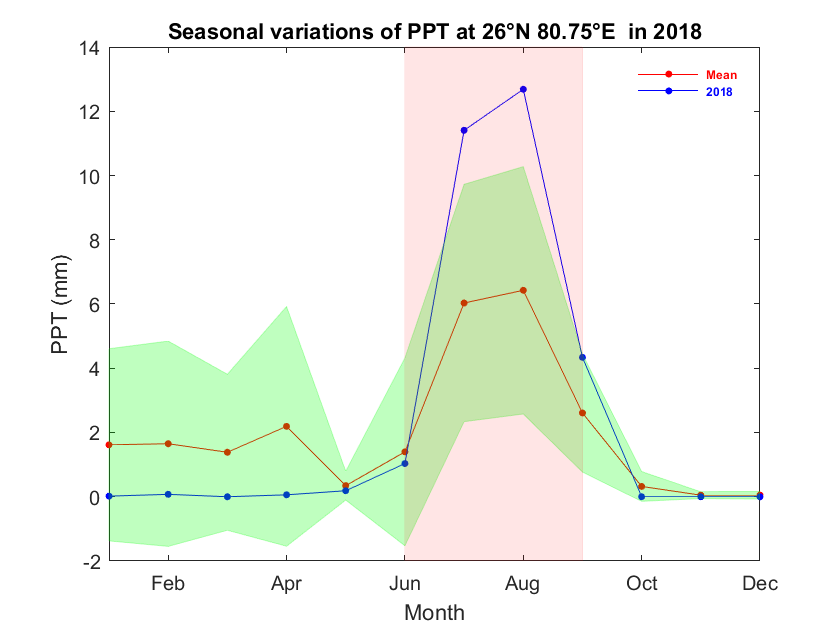




%seasonal variation for PPT
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        
        p_st_u=squeeze(ppt_m(x,y,:)+ppt_s(x,y,:));
        p_st_d=squeeze(ppt_m(x,y,:)-ppt_s(x,y,:));
        pm=squeeze(ppt_m(x,y,:));
        p=squeeze(ppt(x,y,ind_start:ind_end));
        
        
        f1=figure(1);
        plot(pm,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(p,"-o",'MarkerSize',3,'MarkerEdgeColor','blue','MarkerFaceColor',"blue","Color","blue");
        ylabel("PPT (mm)");
        %         plot(p_st_u,"g");
        %         plot(p_st_d,"g");
        lgd=legend("\color{red}\bf Mean","\color{blue}\bf "+num2str(year));
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Seasonal variations of PPT"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));
        j=jbfill((1:12),p_st_u',p_st_d',"g","g",1,0.25);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
        q=jbfill((6:9),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
%         q=jbfill((9:12),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
        
    end
end

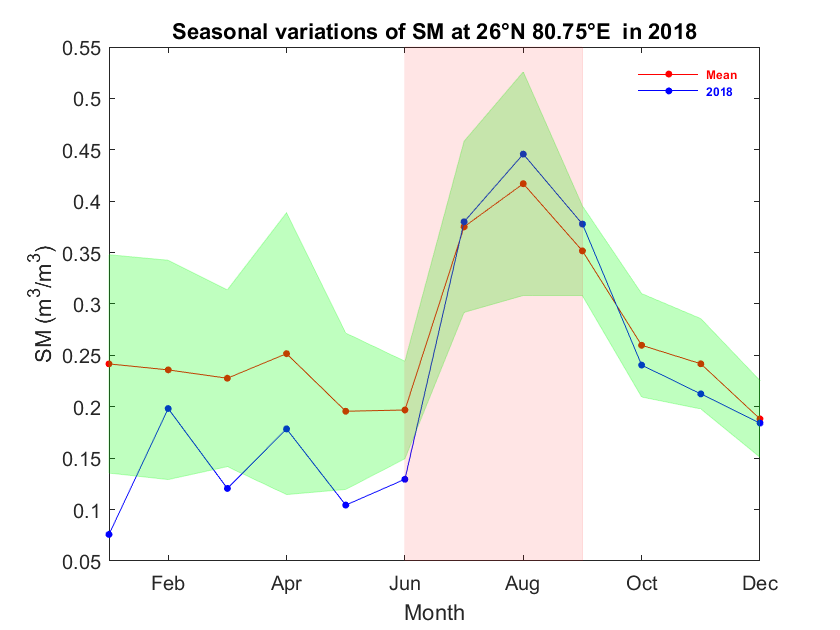


%seasonal variation for SM
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        sm_st_u=squeeze(sm_m(x,y,:)+sm_s(x,y,:));
        sm_st_d=squeeze(sm_m(x,y,:)-sm_s(x,y,:));
        smm=squeeze(sm_m(x,y,:));
        sm=squeeze(sm(x,y,ind_start:ind_end));
        
        
        f2=figure(2);
        plot(smm,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(sm,"-o",'MarkerSize',3,'MarkerEdgeColor','blue','MarkerFaceColor',"blue","Color","blue");
        ylabel("SM (m^3/m^3)");
        %         plot(sm_st_u,"g");
        %         plot(sm_st_d,"g");
        lgd=legend("\color{red}\bf Mean","\color{blue}\bf "+num2str(year));
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Seasonal variations of SM"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));
        j=jbfill((1:12),sm_st_u',sm_st_d',"g","g",1,0.25);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
        q=jbfill((6:9),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
%         q=jbfill((9:12),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
    end
end

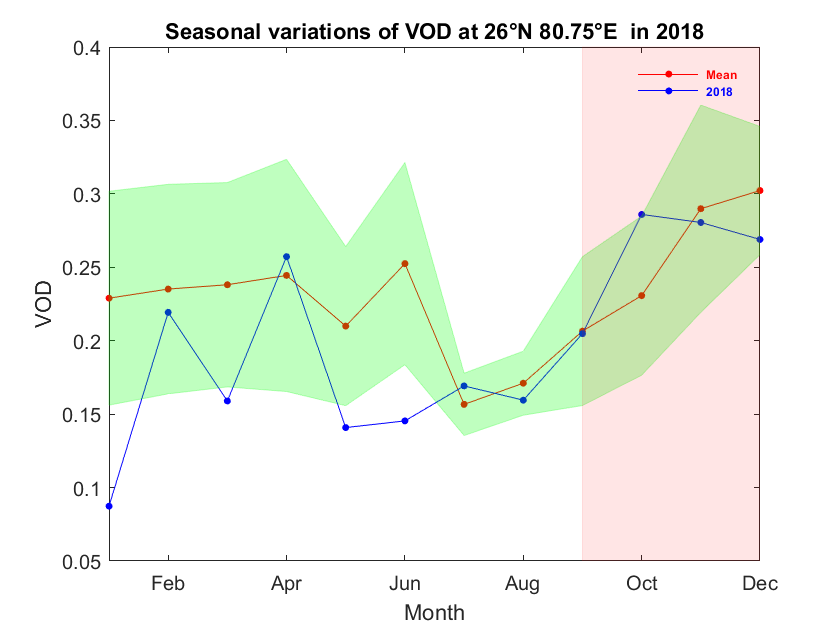


%seasonal variation for VOD
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        vod_st_u=squeeze(vod_m(x,y,:)+vod_s(x,y,:));
        vod_st_d=squeeze(vod_m(x,y,:)-vod_s(x,y,:));
        vodm=squeeze(vod_m(x,y,:));
        vod=squeeze(vod(x,y,ind_start:ind_end));
        
        
        f3=figure(3);
        plot(vodm,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(vod,"-o",'MarkerSize',3,'MarkerEdgeColor','blue','MarkerFaceColor',"blue","Color","blue");
        ylabel("VOD");
        %         plot(vod_st_u,"g");
        %         plot(vod_st_d,"g");
        lgd=legend("\color{red}\bf Mean","\color{blue}\bf "+num2str(year));
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Seasonal variations of VOD"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));        
        j=jbfill((1:12),vod_st_u',vod_st_d',"g","g",1,0.25);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
%         q=jbfill((6:9),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        q=jbfill((9:12),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
    end
end

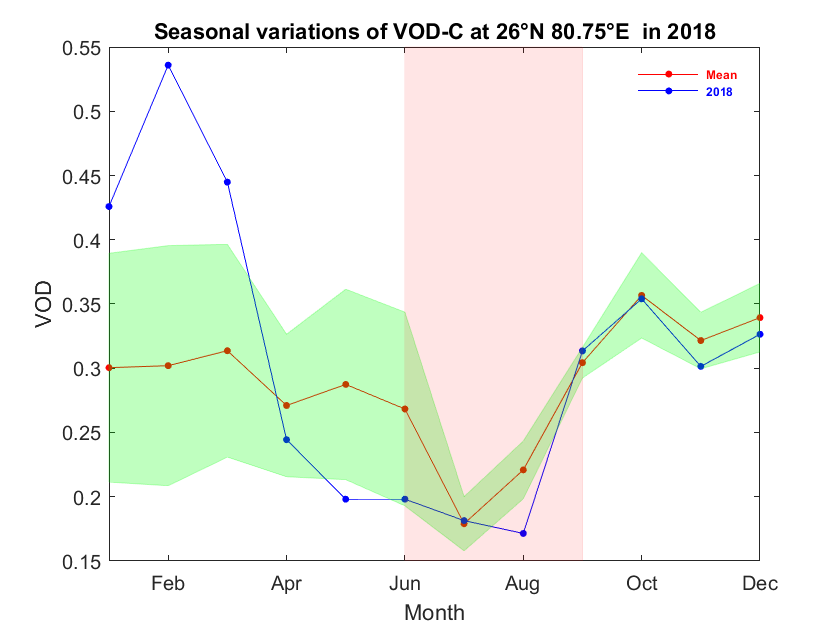



%seasonal variation for VOD-c
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        vod_c_st_u=squeeze(vod_c_m(x,y,:)+vod_c_s(x,y,:));
        vod_c_st_d=squeeze(vod_c_m(x,y,:)-vod_c_s(x,y,:));
        vodm_c=squeeze(vod_c_m(x,y,:));
        vod_c=squeeze(vod_c(x,y,ind_start:ind_end));
        
        
        f18=figure(18);
        plot(vodm_c,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(vod_c,"-o",'MarkerSize',3,'MarkerEdgeColor','blue','MarkerFaceColor',"blue","Color","blue");
        ylabel("VOD");
        %         plot(vod_st_u,"g");
        %         plot(vod_st_d,"g");
        lgd=legend("\color{red}\bf Mean","\color{blue}\bf "+num2str(year));
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Seasonal variations of VOD-C"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));        
        j=jbfill((1:12),vod_c_st_u',vod_c_st_d',"g","g",1,0.25);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
        q=jbfill((6:9),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
%         q=jbfill((9:12),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
    end
end

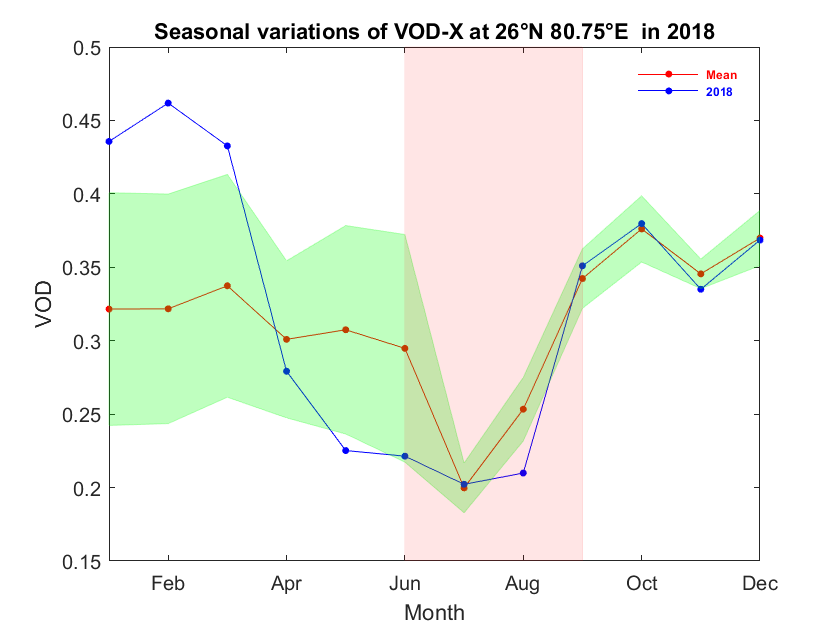


%seasonal variation for VOD-x
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        vod_x_st_u=squeeze(vod_x_m(x,y,:)+vod_x_s(x,y,:));
        vod_x_st_d=squeeze(vod_x_m(x,y,:)-vod_x_s(x,y,:));
        vodm_x=squeeze(vod_x_m(x,y,:));
        vod_x=squeeze(vod_x(x,y,ind_start:ind_end));
        
        
        f8=figure(8);
        plot(vodm_x,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(vod_x,"-o",'MarkerSize',3,'MarkerEdgeColor','blue','MarkerFaceColor',"blue","Color","blue");
        ylabel("VOD");
        %         plot(vod_st_u,"g");
        %         plot(vod_st_d,"g");
        lgd=legend("\color{red}\bf Mean","\color{blue}\bf "+num2str(year));
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Seasonal variations of VOD-X"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));        
        j=jbfill((1:12),vod_x_st_u',vod_x_st_d',"g","g",1,0.25);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
        q=jbfill((6:9),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
%         q=jbfill((9:12),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
    end
end

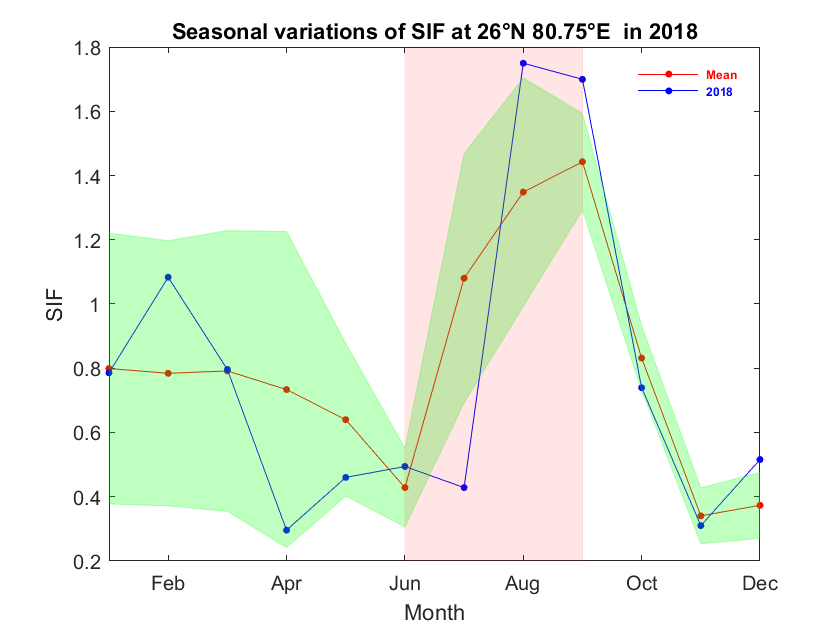


%seasonal variation for SIF
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        sif_st_u=squeeze(sif_m(x,y,:)+sif_s(x,y,:));
        sif_st_d=squeeze(sif_m(x,y,:)-sif_s(x,y,:));
        sifm=squeeze(sif_m(x,y,:));
        sif=squeeze(sif(x,y,ind_start:ind_end));
        
        
        f4=figure(4);
        plot(sifm,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(sif,"-o",'MarkerSize',3,'MarkerEdgeColor','blue','MarkerFaceColor',"blue","Color","blue");
        ylabel("SIF");
        %         plot(sif_st_u,"g");
        %         plot(sif_st_d,"g");
        lgd=legend("\color{red}\bf Mean","\color{blue}\bf "+num2str(year));
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Seasonal variations of SIF"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));
        j=jbfill((1:12),sif_st_u',sif_st_d',"g","g",1,0.25);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
        q=jbfill((6:9),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
%         q=jbfill((9:12),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
    end
end

function[fillhandle,msg]=jbfill(xpoints,upper,lower,color,edge,add,transparency)
%USAGE: [fillhandle,msg]=jbfill(xpoints,upper,lower,color,edge,add,transparency)
%This function will fill a region with a color between the two vectors provided
%using the Matlab fill command.
%
%fillhandle is the returned handle to the filled region in the plot.
%xpoints= The horizontal data points (ie frequencies). Note length(Upper)
%         must equal Length(lower)and must equal length(xpoints)!
%upper = the upper curve values (data can be less than lower)
%lower = the lower curve values (data can be more than upper)
%color = the color of the filled area
%edge  = the color around the edge of the filled area
%add   = a flag to add to the current plot or make a new one.
%transparency is a value ranging from 1 for opaque to 0 for invisible for
%the filled color only.
%
%John A. Bockstege November 2006;
%Example:
%     a=rand(1,20);%Vector of random data
%     b=a+2*rand(1,20);%2nd vector of data points;
%     x=1:20;%horizontal vector
%     [ph,msg]=jbfill(x,a,b,rand(1,3),rand(1,3),0,rand(1,1))
%     grid on
%     legend('Datr')
if nargin<7;transparency=.5;end %default is to have a transparency of .5
if nargin<6;add=1;end     %default is to add to current plot
if nargin<5;edge='k';end  %dfault edge color is black
if nargin<4;color='b';end %default color is blue

if length(upper)==length(lower) && length(lower)==length(xpoints)
    msg='';
    filled=[upper,fliplr(lower)];
    xpoints=[xpoints,fliplr(xpoints)];
    if add
        hold on
    end
    fillhandle=fill(xpoints,filled,color);%plot the data
    set(fillhandle,'EdgeColor',edge,'FaceAlpha',transparency,'EdgeAlpha',transparency);%set edge color
    if add
        hold off
    end
else
    msg='Error: Must use the same number of points in each vector';
end
end